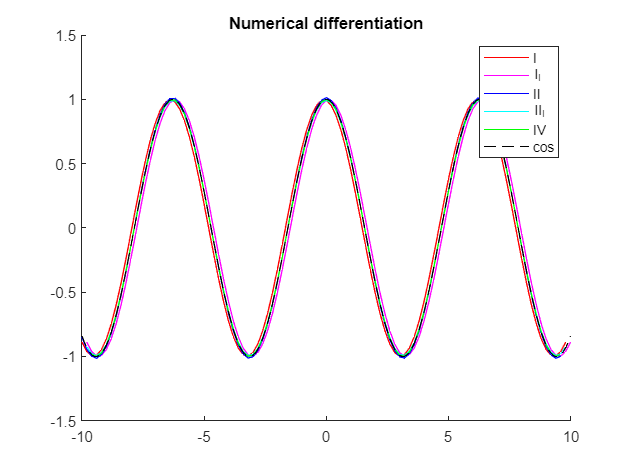

begin = -10;
step = 0.2;
ending = 10;
xc = linspace(begin, ending, 1000);
x = begin:step:ending;

[I, I_l, II, II_l, IV] = Agregator(x,sin(x));

hold on
plot((begin:step:ending-step),I, 'r')
plot((begin+step:step:ending),I_l, 'm')
plot((begin:step:ending-2*step), II, 'b')
plot((begin+step:step:ending-step), II_l, 'c')
plot((begin+2*step:step:ending-2*step),IV, 'g')
plot(xc, cos(xc), 'black--')
legend('I', 'I_l', 'II', 'II_l', 'IV', 'cos')
title('Numerical differentiation')
hold off

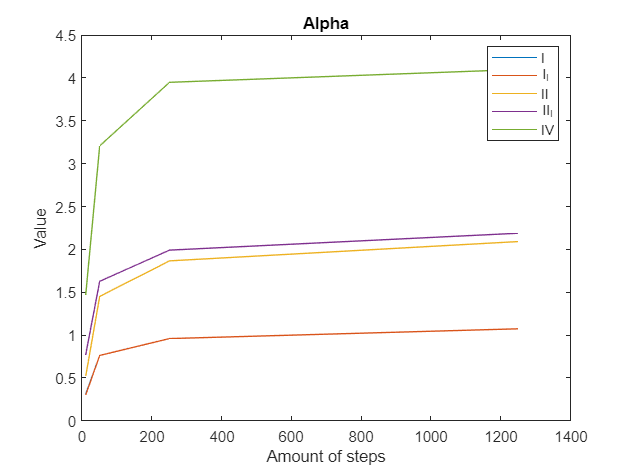

begin_t = 0;
step_t = 1;
ending_t = 10;
% alph = zeros(4,4);
% C_val = zeros(4,2);
% step_val = zeros(4,1);

for i = 1:4
    x_test = begin_t:step_t:ending_t;
    [I_test, I_l_test, II_test, II_l_test, IV_test] = Agregator(x_test, sin(x_test));
    alph(i, 1) = -log(max(abs(cos((begin_t:step_t:ending_t-step_t)) - I_test))) / log(length(x_test)); 
    alph(i, 2) = -log(max(abs(cos((begin_t+step_t:step_t:ending_t)) - I_l_test))) / log(length(x_test)); 
    alph(i, 3) = -log(max(abs(cos((begin_t:step_t:ending_t-2*step_t)) - II_test))) / log(length(x_test)); 
    alph(i, 4) = -log(max(abs(cos((begin_t+step_t:step_t:ending_t-step_t)) - II_l_test))) / log(length(x_test)); 
    alph(i, 5) = -log(max(abs(cos((begin_t+2*step_t:step_t:ending_t-2*step_t)) - IV_test))) / log(length(x_test));
    C_val(i,1) = (max(abs(cos((begin_t:step_t:ending_t-2*step_t)) - II_test))) / (step_t^2);
    C_val(i,2) = (max(abs(cos((begin_t+step_t:step_t:ending_t-step_t)) - II_l_test))) / (step_t^2);
    step_t = step_t/10;
    ending_t = ending_t/2;
    step_val(i) = length(x_test);
end

plot(step_val,alph)
legend('I', 'I_l', 'II', 'II_l', 'IV')
xlabel('Amount of steps')
ylabel('Value')
title('Alpha')

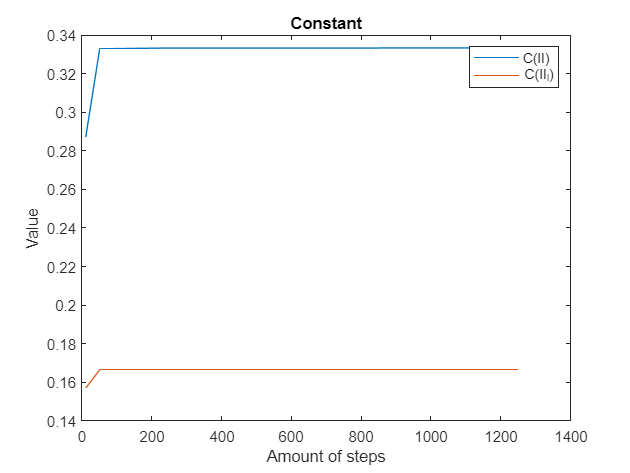



plot(step_val, C_val)
legend('C(II)', 'C(II_l)')
xlabel('Amount of steps')
ylabel('Value')
title('Constant')

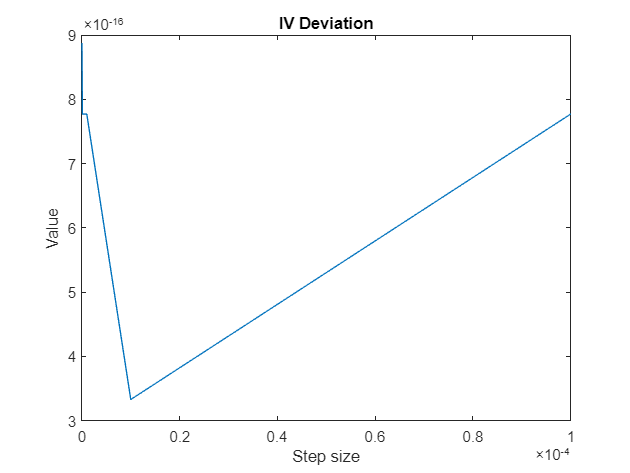

begin_br = 0;
step_br = 0.0001;
ending_br = 0.001;
% max_dev = zeros(5,1);
% step_val_br = zeros(5,1);

for i = 1:5
    x_br = begin_br:step_br:ending_br;
    [~,~,~,~,IV_br] = Agregator(x_br,sin(x_br));
    max_dev(i) = max(abs(cos(begin_br+2*step_br:step_br:ending_br-2*step_br) - IV_br));
    step_val_br(i) = step_br;
    step_br = step_br / 10;
    ending_br = ending_br / 10;
end

plot(step_val_br, max_dev)
xlabel('Step size')
ylabel('Value')
title('IV Deviation')